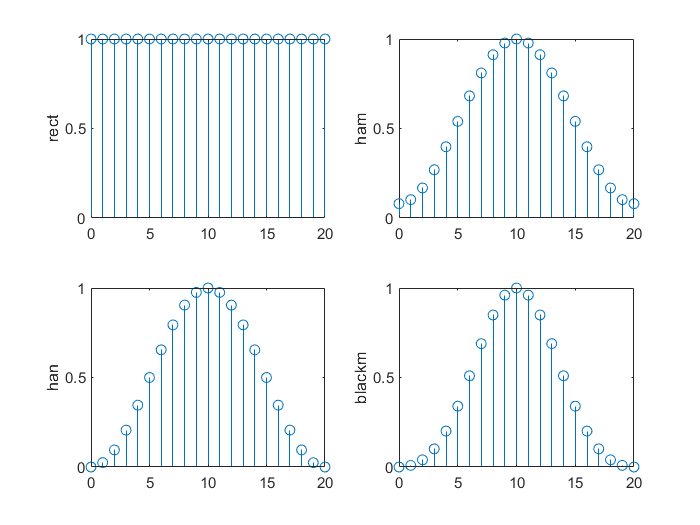

clear;clc;close all;
N=0:20;
rect=ones(21,1);
ham=hamming(21);
han=hann(21);
blackm=blackman(21);

figure(1);
subplot(221);stem(N,rect);ylabel('rect');
subplot(222);stem(N,ham);ylabel('ham');
subplot(223);stem(N,han);ylabel('han');
subplot(224);stem(N,blackm);ylabel('blackm')

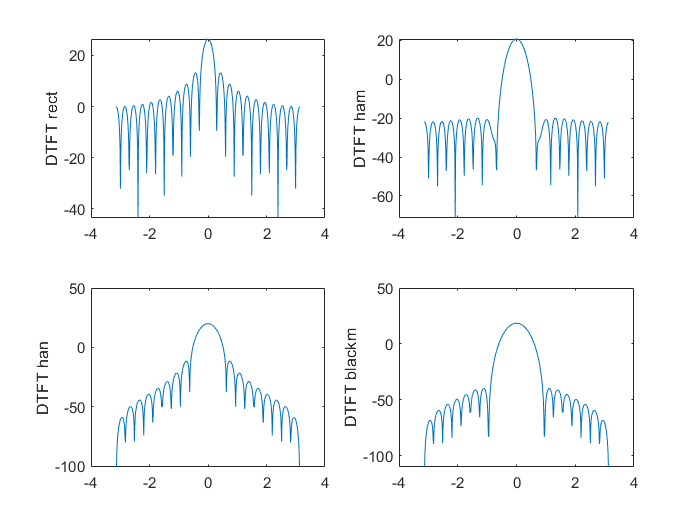

[X1,w1]=DTFT(rect,512);
[X2,w2]=DTFT(ham,512);
[X3,w3]=DTFT(han,512);
[X4,w4]=DTFT(blackm,512);

figure(2);
subplot(221);plot(w1,20*log10(abs(X1)));ylabel('DTFT rect');
subplot(222);plot(w2,20*log10(abs(X2)));ylabel('DTFT ham');
subplot(223);plot(w3,20*log10(abs(X3)));ylabel('DTFT han');
subplot(224);plot(w4,20*log10(abs(X4)));ylabel('DTFT blackm');

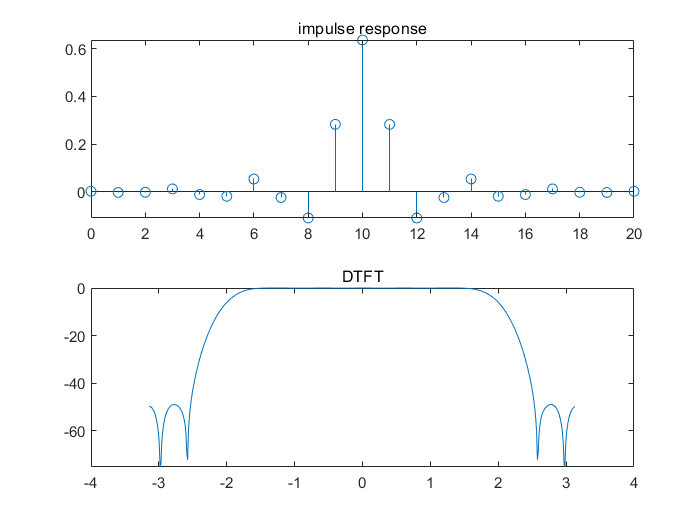

h=(2/pi).*sinc(2/pi.*(N-10))';
H=h.*ham;
[X5,w5]=DTFT(H,512);
figure(3);
subplot(211);stem(N,H);title('impulse response');
subplot(212);plot(w5,20*log10(abs(X5)));title('DTFT');